part 2

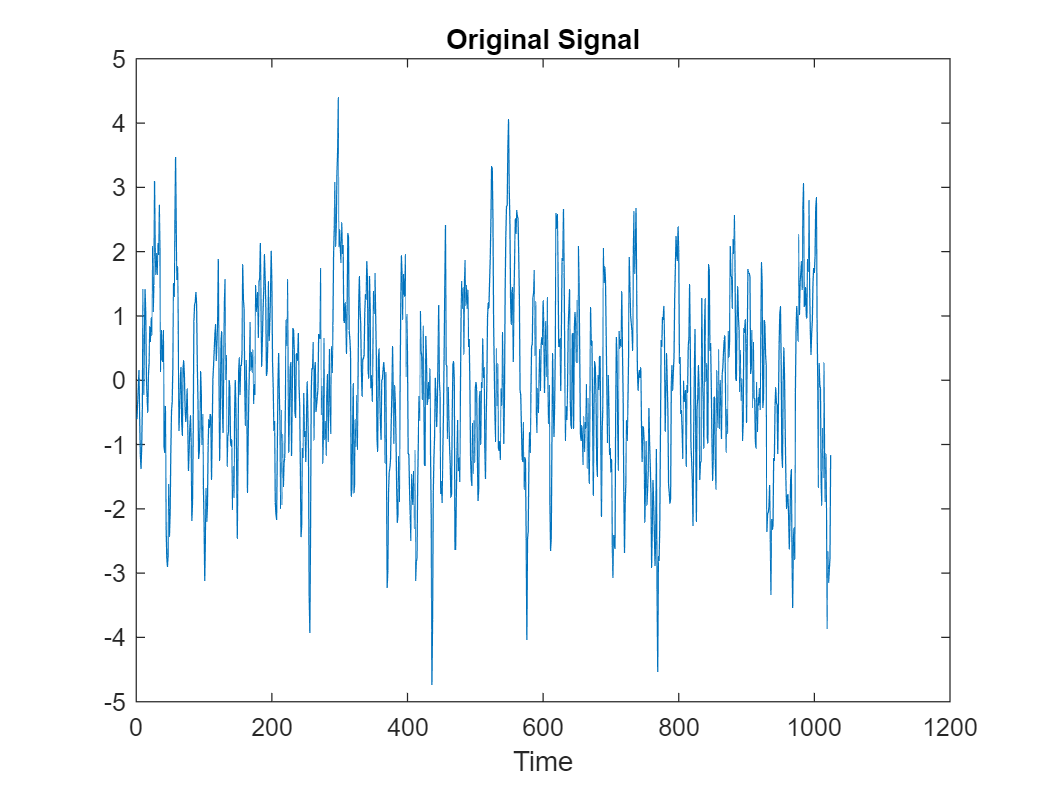

N = 1024; %The sample rate

% The value of the variance according to the analytical calculation
sigma_w = sqrt(0.72);
sigma_v = sqrt(2);

% Generate the signals
w = sigma_w*randn(1,2*N);
x_2048 = filter(1,[1,-0.8],w); 
x = x_2048(N+1:2*N);

v = sigma_v*randn(1,N);
y = x + v;

% display the signals
plot(x);
title('Original Signal');
xlabel('Time');

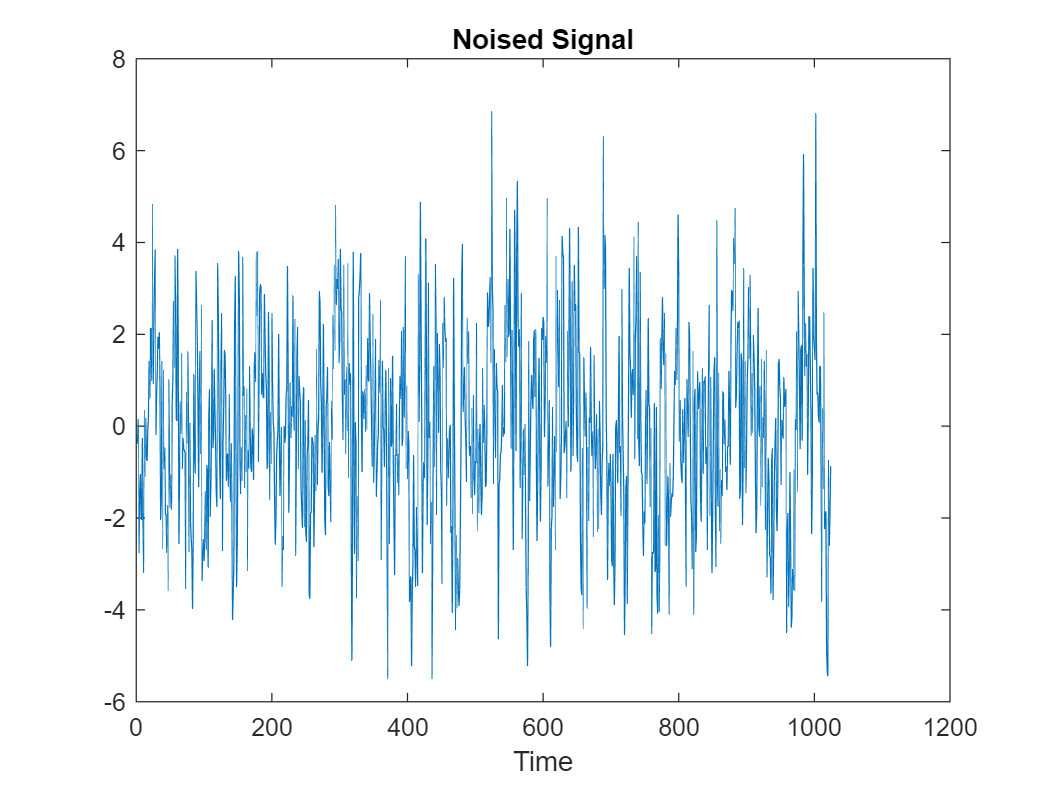


plot(y);
title('Noised Signal');
xlabel('Time');

part 3

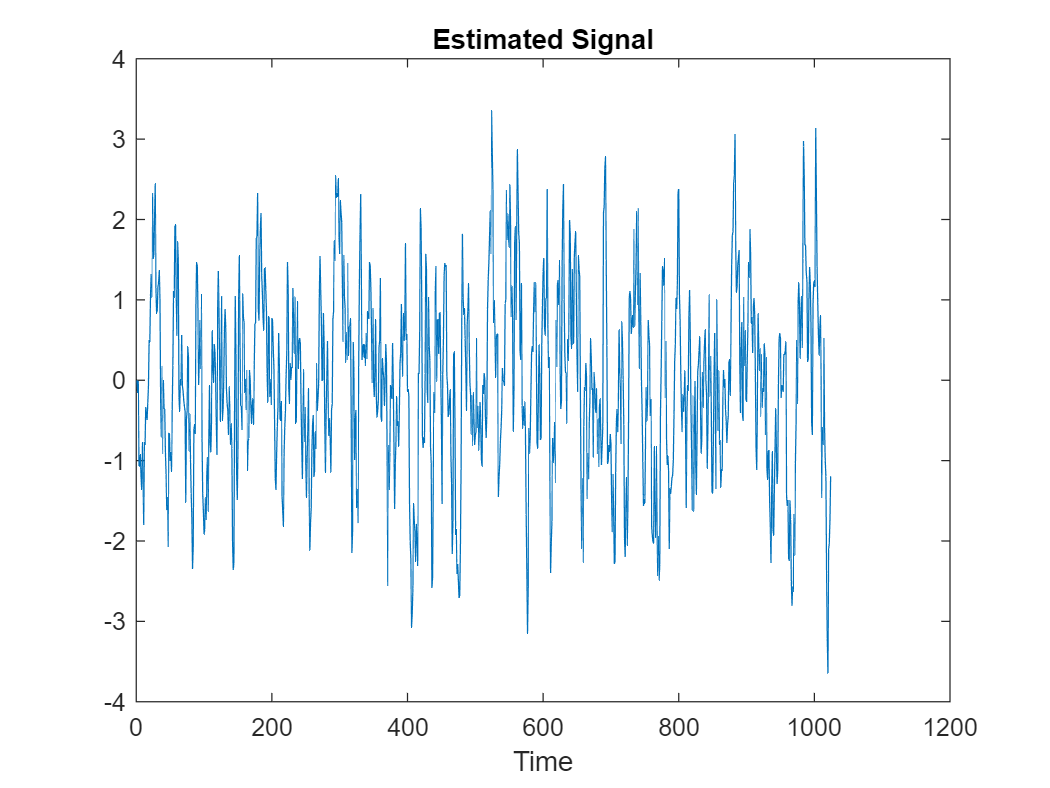

[x_e, p_e] = kalman_filter(y, N);

plot(x_e);
title('Estimated Signal');
xlabel('Time');

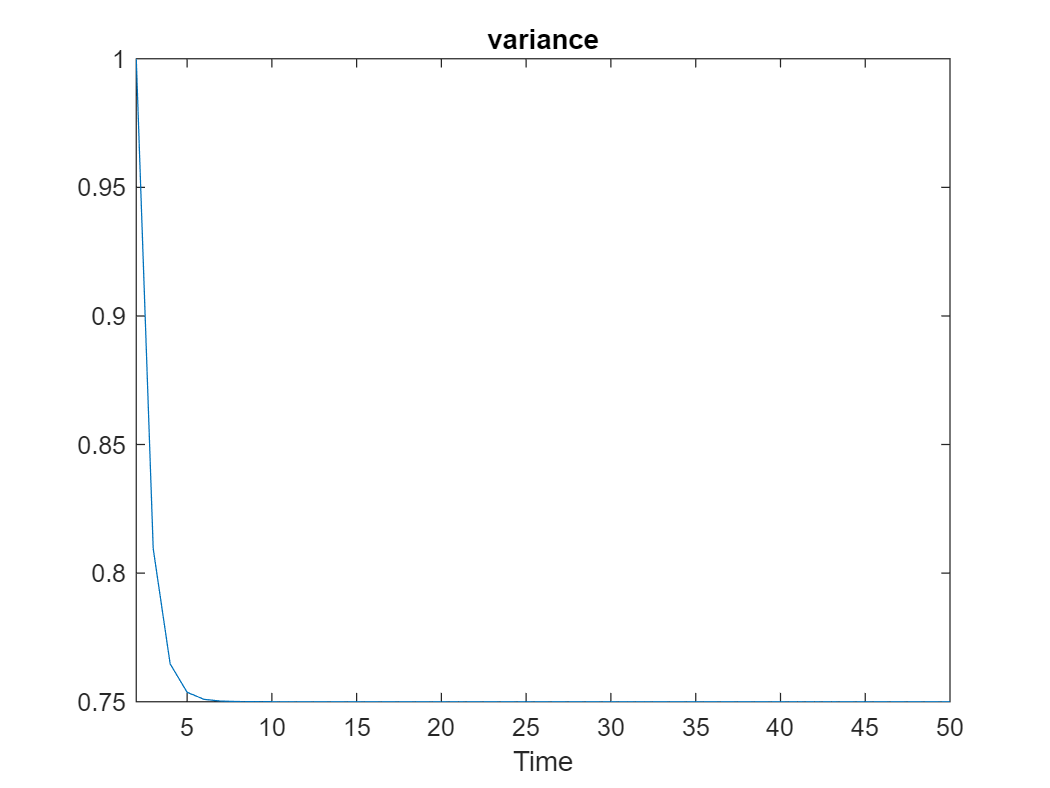


plot(p_e);
title('variance');
xlabel('Time');
xlim([2, 50]);